# Varying correlation; gap timing

## load and preprocess data

fds = fileDatastore('A1-*.mat', 'ReadFcn', @importdata);
Filenames = fds.Files;
ncorr = length(Filenames);

C = cell(1,ncorr);
for i = 1:ncorr
    load(Filenames{i});
    C{1,i} = c;
end

c = cat(1,C{1,:});

nparams = size(c,1); % number of sets of firing rate parameters
ntrials = size(c,2)-5; % number of trials
Corr = zeros(nparams, ntrials);
RT = zeros(nparams, ntrials);
for i = 1:nparams
    for j = 1:ntrials
        Corr(i,j)=c{i,j}.corr;
        RT(i,j) = c{i,j}.performance(1,3);
    end
end

params = c(:,ntrials+1:ntrials+5);
params = cell2mat(params);
lambda1 = params(:,1);
lambda2 = params(:,2);
k1 = params(:,3);
k2 = params(:,4);
fr_exact = params(:,5);
fr = round(fr_exact,-1); % round firing rate to nearest 10 Hz
fr2 = lambda2./k2;
burstiness = k1./lambda1;
RT = median(RT,2);

Corr = median(Corr,2);
Corr(Corr<0)=0;
corr_edges = 0:0.1:1;
corr_bin = discretize(Corr,corr_edges);
corr_vals = 1:length(corr_edges)-1;
corr_vec1 = 0:0.1:1;
corr_vec2 = 0.05:0.1:0.95;

## analyze data

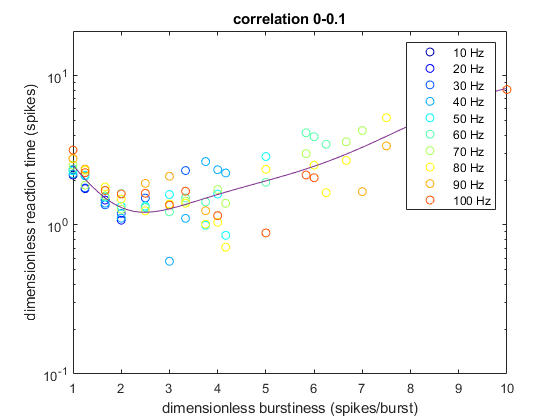

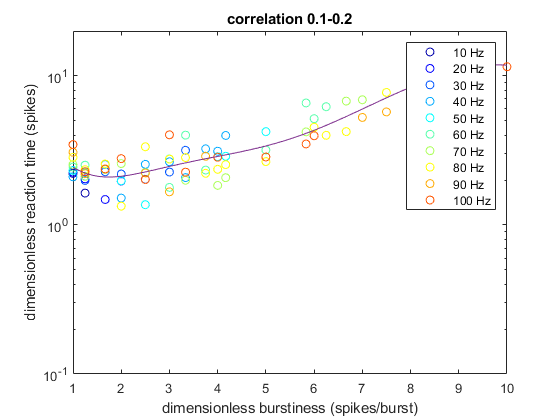

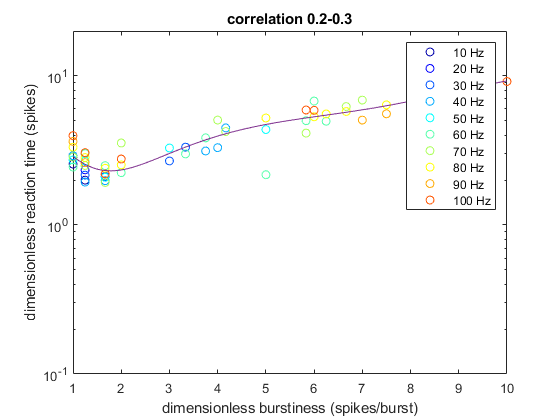

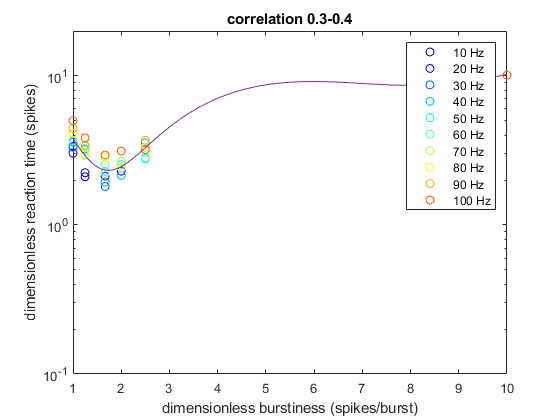

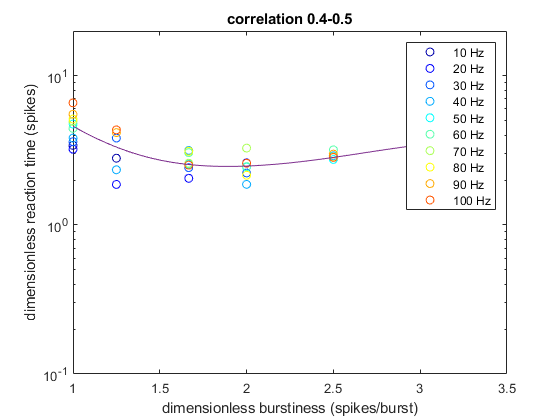

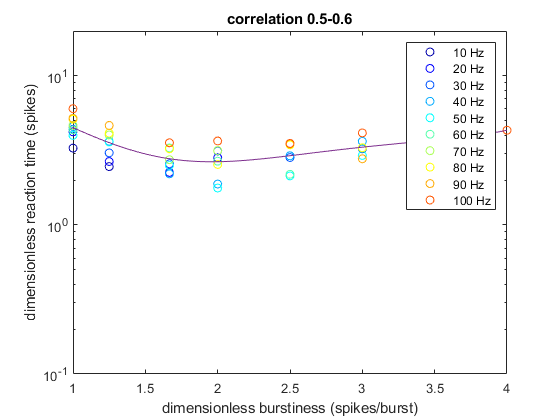

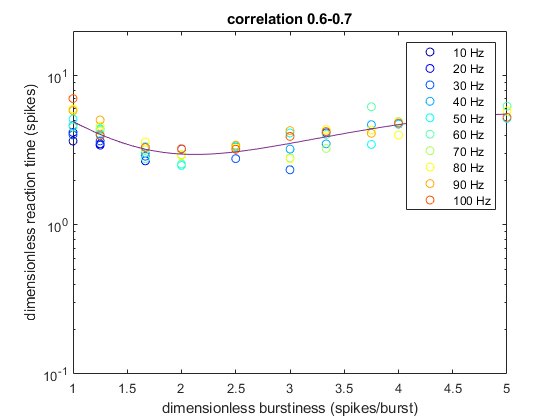

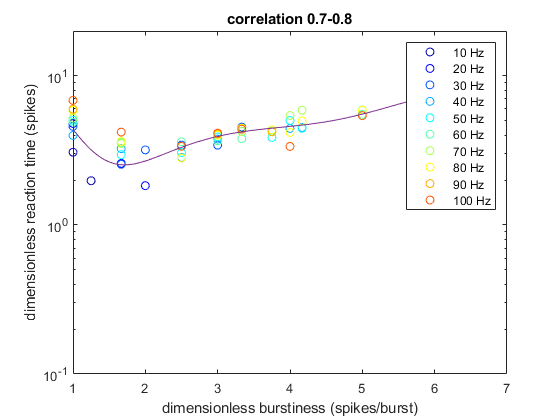

% generate a random color for each firing rate
mycolors = jet(10);
fr_vals = 10:10:100;

P = zeros(length(corr_vals),6); % preallocate matrix to hold polynomial coeff for each correlation bin
for k = 1:length(corr_vals)
    figure;
    rows = find(corr_bin== k);
    y = RT(rows).*fr_exact(rows)./1000;
    x = fr2(rows);

    % average together y values with the same firing rate and x value
    x1 = [];
    y1 = [];
    for i = 1:length(fr_vals)
        rows2 = find(fr(rows) == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        semilogy(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
        x1 = [x1; x_vals];
        y1 = [y1; y_vals];
        hold on
    end
    % now average together all y values with the same x value
    x2 = unique(x1);
    y2 = zeros(length(x2),1);
    for j = 1:length(x2)
        y2(j) = median(y1(x1 == x2(j)));
    end
    TF = ~isnan(y2);
    y2 = y2(TF);
    x2 = x2(TF);
    xx = 1:0.01:max(x2);
    p = polyfit(x2,y2,5);
    yy = polyval(p,xx);
    semilogy(xx,yy)
    hold off
    ylabel('dimensionless reaction time (spikes)')
    xlabel('dimensionless burstiness (spikes/burst)')
    title(['correlation ', num2str(corr_vec1(k)), '-', num2str(corr_vec1(k+1))])
    ylim([0.1 20])
    legend('10 Hz','20 Hz','30 Hz','40 Hz','50 Hz','60 Hz','70 Hz','80 Hz','90 Hz','100 Hz')
    P(k,:) = p;
end

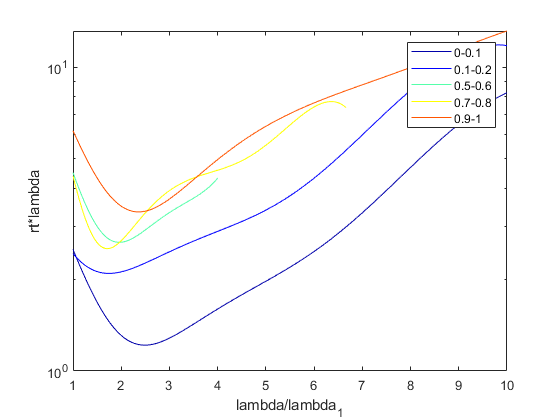

% choose 5 correlations (for the sake of readability) and plot the
% corresponding polynomial fits
mycorrs = [1 2 6 8 10];
for k = 1:length(mycorrs)
    rows = find(corr_bin== mycorrs(k));
    rt = RT(rows);
    lambda_s = fr_exact(rows);
    lambda_s_round = fr(rows);
    y = rt.*lambda_s./1000;
    x = fr2(rows);

    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(lambda_s_round == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
    end
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    fit_error = zeros(length(fit_x),1);
    for j = 1:length(fit_x)
        fit_y(j) = median(all_y(all_x == fit_x(j)));
        fit_error(j) = iqr(all_y(all_x == fit_x(j)));
    end
    xq = 1:0.01:max(fit_x);
    yq = interp1(fit_x,fit_y,xq,'spline');
    xx = 1:0.01:max(fit_x);
    p = polyfit(fit_x,fit_y,5);
    yy = polyval(p,xx);
    semilogy(xx,yy,'color',mycolors(mycorrs(k),:))
    hold on
    ylabel('rt*lambda')
    xlabel('lambda/lambda_1')
    M1(1:length(xx),k*2-1:k*2) = [xx.' yy.'];
end
hold off
legend('0-0.1','0.1-0.2','0.5-0.6','0.7-0.8','0.9-1')

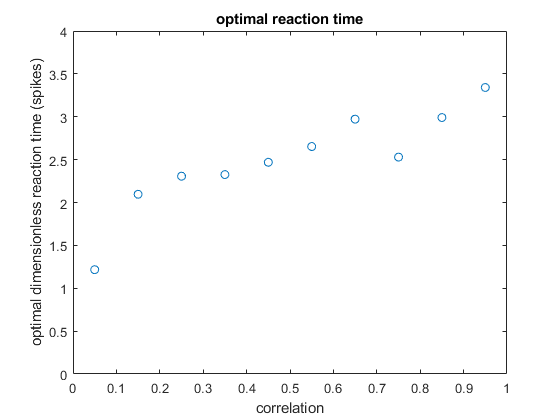

close all hidden;
optimal_burst_prediction = zeros(length(corr_vals),1);
optimal_rt_prediction = zeros(length(corr_vals),1);
for k = 1:length(corr_vals)
    rows = find(corr_bin== k);
    xx = 1:0.01:max(fr2(rows));
    p = P(k,:);
    yy = polyval(p,xx);
    [~,min_ind] = min(yy);    
    optimal_burst_prediction(k) = xx(min_ind);
    optimal_rt_prediction(k) = yy(min_ind);
end

plot(corr_vec2,optimal_rt_prediction, 'o')
ylim([0 4])
ylabel('optimal dimensionless reaction time (spikes)')
xlabel('correlation')
title('optimal reaction time')

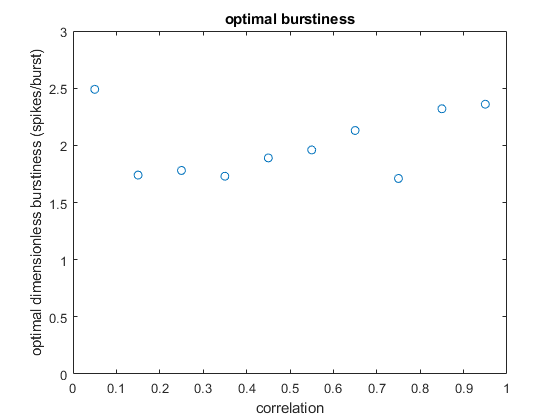


plot(corr_vec2,optimal_burst_prediction, 'o')
ylim([0 3])
ylabel('optimal dimensionless burstiness (spikes/burst)')
xlabel('correlation')
title('optimal burstiness')

## example plots shown in paper

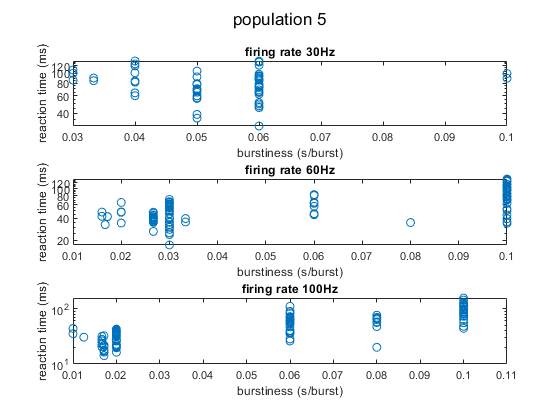

my_vals = [3 6 10];
for k = 1:length(my_vals)
    rows = find(fr == fr_vals(my_vals(k)) & corr_bin== 3);
    burstinessj = burstiness(rows);
    rt = RT(rows);
    subplot(3,1,k)
    semilogy(burstinessj,rt,'o')
    ylabel('reaction time (ms)')
    xlabel('burstiness (s/burst)')
    title(['firing rate ', num2str(fr_vals(my_vals(k))), 'Hz'])
end
sgtitle('population 5')

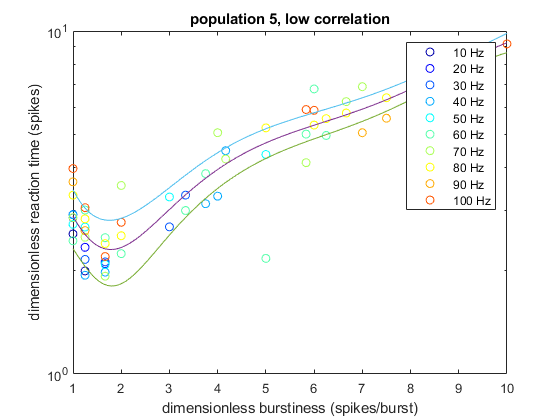

close all hidden;
rows = find(corr_bin== 3);
rt = RT(rows);
lambda_s = fr_exact(rows);
lambda_s_round = fr(rows);
y = rt.*lambda_s./1000;
x = fr2(rows);

all_x = [];
all_y = [];
for i = 1:length(fr_vals)
    rows2 = find(lambda_s_round == fr_vals(i));
    this_x = x(rows2);
    this_y = y(rows2);
    x_vals = unique(this_x);
    y_vals = zeros(length(x_vals),1);
    for j = 1:length(x_vals)
        y_vals(j) = median(this_y(this_x == x_vals(j)));
    end
    semilogy(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
    all_x = [all_x; x_vals];
    all_y = [all_y; y_vals];
    hold on
end
fit_x = unique(all_x);
fit_y = zeros(length(fit_x),1);
fit_error = zeros(length(fit_x),1);
for j = 1:length(fit_x)
    fit_y(j) = median(all_y(all_x == fit_x(j)));
    fit_error(j) = iqr(all_y(all_x == fit_x(j)));
end
xq = 1:0.01:10;
yq = interp1(fit_x,fit_y,xq,'spline');
xx = 1:0.01:10;
[p, S, mu] = polyfit(fit_x,fit_y,5);
[yy, delta] = polyval(p,xx,S, mu);
semilogy(xx,yy)
hold on
semilogy(xx,yy-delta)
hold on
semilogy(xx,yy+delta)
hold off
ylabel('dimensionless reaction time (spikes)')
xlabel('dimensionless burstiness (spikes/burst)')
title('population 5, low correlation')
legend('10 Hz','20 Hz','30 Hz','40 Hz','50 Hz','60 Hz','70 Hz','80 Hz','90 Hz','100 Hz')
ylim([1 10])